clear;clc;

测试代码。

没什么详细含义。

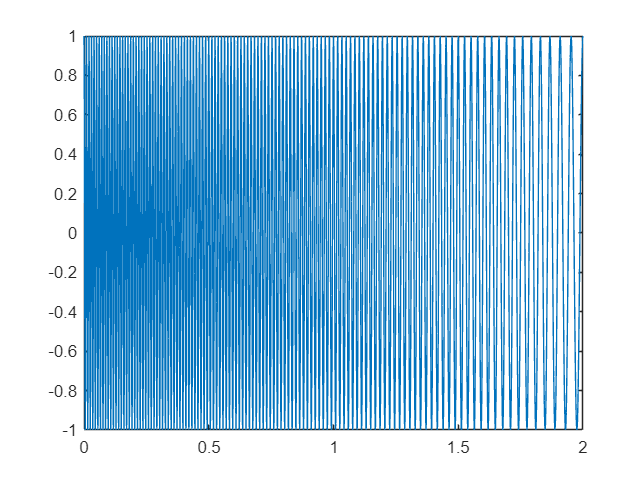

t = 0:1e-6:2;
y = chirp(t,100,2,20);
figure();
plot(t,y);

LFM信号产生采用chirp()函数，方法：

chirp(时间轴，起始频率/Hz，调频时宽/s，终止频率/Hz)

上述方法产生的LFM信号并非脉冲，chirp()函数只标定调频系数。

下面测试使用phased类中生成LFM信号的方法。

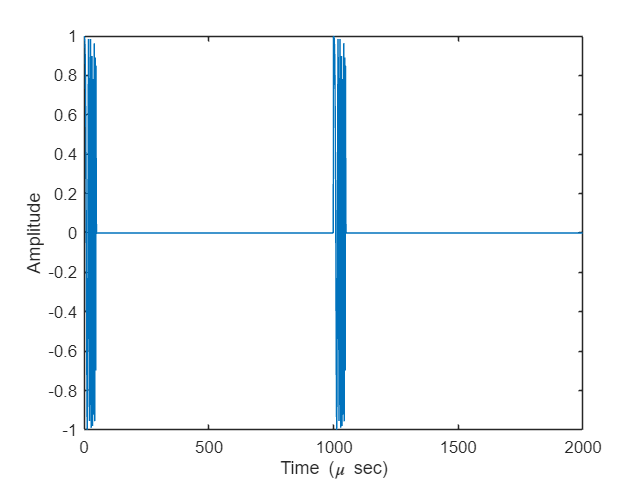

sLFM = phased.LinearFMWaveform('SweepBandwidth',3e5,...
    'OutputFormat','Pulses','SampleRate',1e6,...
    'PulseWidth',50e-6,'PRF',1e3,'NumPulses',2);
wav = step(sLFM);
numpulses = size(wav,1);
t = (0:(numpulses-1))/sLFM.SampleRate;
plot(t*1e6,real(wav));
xlabel('Time (\mu sec)')
ylabel('Amplitude')

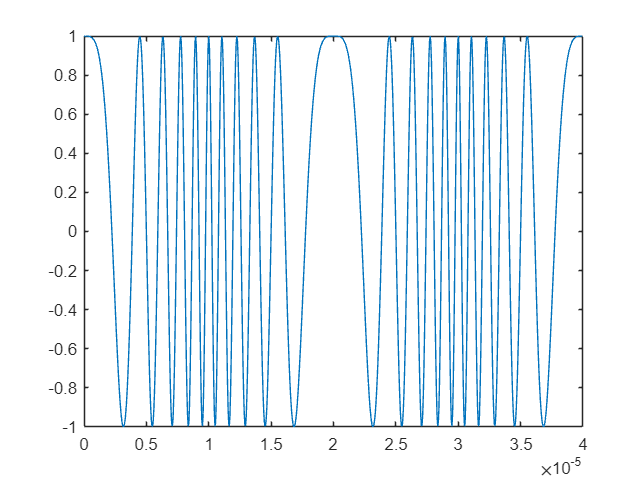

sFMCW = phased.FMCWWaveform('SweepBandwidth',1e6,...
   'SampleRate',20e6,'SweepDirection','Triangle',...
   'NumSweeps',4,'SweepTime',1e-5);
sig = step(sFMCW);
numpulses = size(sig,1);
t = (0:(numpulses-1))/sFMCW.SampleRate;
plot(t,real(sig));

[S,F,T]=stft(sig,fs,"Window",ones(64,1),'OverlapLength',63,'FFTLength',512);

错误使用 zeros
请求的 512x2399937x1 (18.3GB)数组超过预设的最大数组大小(15.7GB)。这可能会导致 MATLAB 无响应。

出错 computeDFT>computeDFTviaFFT (第 81 行)
xw = zeros(nfft,xin_ncol,xin_nchan,'like',xin);

出错 computeDFT (第 45 行)
    [Xx,f] = computeDFTviaFFT(xin,nx,nfft(1),Fs);

出错 <a 

mesh(T,F,abs(S));view(2);